# Résolution de l'équation de Blasius par la méthode de tir


$$f'''+\frac{1}{2} f \,f" =0$$


avec $f(0)=0$, $f'(0)=0$ et $f'(inf)=1$

clc
clear all
close all

## **Résolution numérique**

**Définition du système à résoudre : ****voir à la fin**

**Paramètre de tir** $s=f''(0)$ à faire varier pour vérifier $f'(\infty) = 1$

s=0.33205;    

Solution initiale

y0=zeros(3,1);
y0(1) = 0;
y0(2) = 0;
y0(3) = s;

Paramètres de résolution numérique

options = odeset('RelTol',1e-9, 'AbsTol',1e-8);
eta_in  = 0:0.001:20; % Valeurs de eta pour lesquelles on souhaite une valeur

**Résolution Numérique** par Runge-Kutta

[eta,Y]  = ode45(@blasius_system,eta_in,y0);
f        = Y(:,1);
f_prime  = Y(:,2);
f_second = Y(:,3);
f_prime_end = f_prime(end) % Vérification valeur finale de f' => Jouer avec s

f_prime_end = 1.0000

Tracé de la solution

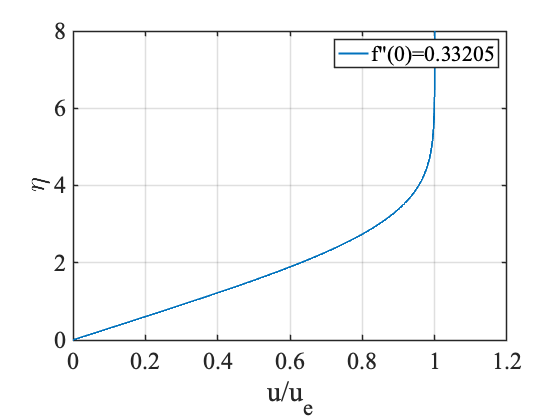

figure(1)
plot(f_prime,eta)
txt=['f"(0)=',num2str(s)];
legend(txt)
set(gca,'fontsize',24,'fontname','times','linewidth',1.5)
ylabel('\eta','fontname','times','fontsize',28)
xlabel('u/u_e','fontname','times','fontsize',28)
set(get(gca,'children'),'linewidth',2)
grid on
xlim([0 1.2])
ylim([0 8])

## Calcul des grandeurs caractéristiques de couche limite

- Calcul du coefficient d'épaisseur de couche limite $\delta_{99}/\delta$ par interpolation du profil $f'(\eta)$

eta_99 = interp1(f_prime, eta, 0.99, 'spline')

eta_99 = 4.9089

- Calcul du coeff. d'épaisseur de déplacement $\delta^*/\delta$

coeff_delta_star = trapz(eta,1-f_prime) 

coeff_delta_star = 1.7203

 La fonction trapz permet de calculer une intégrale par la méthode des trapèzes.

- Calcul du coeff. d'épaisseur de quantité de mouvement $\theta/\delta$

coeff_theta = trapz(eta,f_prime.*(1-f_prime)) 

coeff_theta = 0.6636

##  Reconstruction du champ de vitesse $u(x,y)$

 Vitesse externe

u_e = 10.0;

Viscosité

nu = 1.0e-5;

Longueur plaque et épaisseur couche limite

L = 10e-2;
Re_L = u_e*L/nu;
delta_CL_end = eta_99*L/sqrt(Re_L);

 Domaine

nx = 100;
x  = linspace(0,L,nx);

ny = 500;
y  = linspace(0,5*delta_CL_end,ny);

Champs dans la Couche limite

delta_CL = zeros(1,nx);
delta_CL(2:end) = x(2:end)./sqrt(u_e*x(2:end)/nu);
u=u_e*ones(nx,ny);
for i=2:nx
    my_eta = y(:)/delta_CL(i);
    u(i,:) = u_e*interp1(eta, f_prime, my_eta, 'spline');
end

 Figure

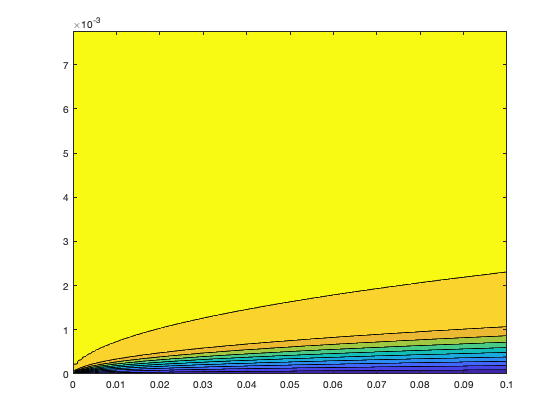

figure(2)
contourf(x,y,u',0:10)
shading interp

**Définition du système à résoudre**

function dy = blasius_system(~,y)
dy = zeros(3,1);
dy(1) = y(2);
dy(2) = y(3);
dy(3) = -0.5*y(1)*y(3); 
end